# ThermoeconomicTool demo

Analyze an ORC system with IHE

#### **(1) Read data model **

Read the data file and create the model with some parameters. 

filename="D:\Documents\Termoeconomia\TaesLab\Examples\rorc\rorc_model.json";
model=ThermoeconomicModel(filename,...
    'CostTables','ALL',...
    'DiagnosisMethod','WASTE_INTERNAL',...
    'Debug',false);

#### **(2) Show the results for Reference State**

Print the result tables and show ICT and waste allocation graphs

ShowResults(model);

Flows Definition Table

  Id Key   From    To      Type      
——————————————————————————————————————
   1 B1    BLR_P1  TRB_F1  INTERNAL  
   2 B2    TRB_F1  IHE_F1  INTERNAL  
   3 B3    IHE_F1  CND_F1  INTERNAL  
   4 B4    CND_F1  PMP_P1  INTERNAL  
   5 B5    PMP_P1  IHE_P1  INTERNAL  
   6 B6    IHE_P1  BLR_P1  INTERNAL  
   7 QBLR  ENV_R1  BLR_F1  RESOURCE  
   8 WP    TRB_P1  PMP_F1  INTERNAL  
   9 WN    TRB_P1  ENV_O1  OUTPUT    
  10 QCND  CND_P1  ENV_W1  WASTE     


Productive Groups Definition Table

  Id Key     Definition  Type      
————————————————————————————————————
   1 BLR_F1  QBLR        FUEL      
   2 BLR_P1  B1-B6       PRODUCT   
   3 TRB_F1  B1-B2       FUEL      
   4 TRB_P1  WN+WP       PRODUCT   
   5 IHE_F1  B2-B3       FUEL      
   6 IHE_P1  B6-B5       PRODUCT   
   7 PMP_F1  WP          FUEL      
   8 PMP_P1  B5-B4       PRODUCT   
   9 CND_F1  B3-B4       FUEL      
  10 CND_P1  QCND        PRODUCT   
  11 ENV_R1  QBLR        RESOURCE  
  12 ENV_O1 

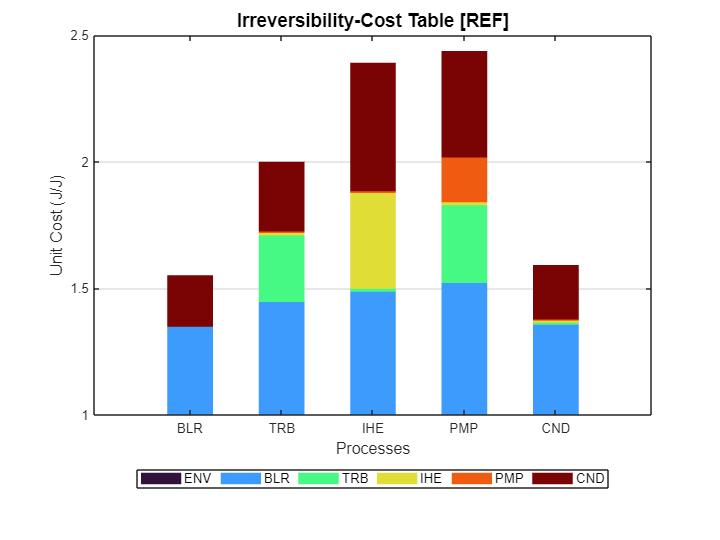

model.showGraph(cType.Tables.PROCESS_ICT);

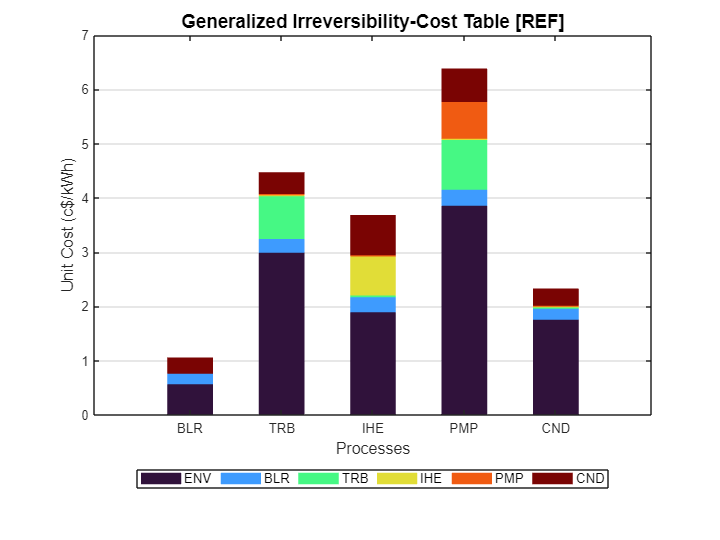

model.showGraph(cType.Tables.PROCESS_GENERAL_ICT);

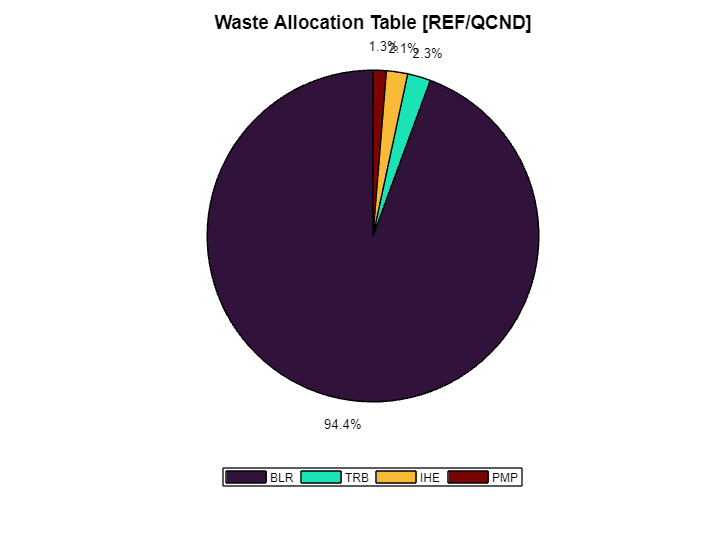

showGraph(model,cType.Tables.WASTE_ALLOCATION);

#### **(3) Summary Results**

Show unit cost summary tables and graph

model.Summary=true;
res=model.summaryResults;
ShowResults(res,'Table',cType.Tables.SUMMARY_FLOW_UNIT_COST);

Summary Flows Direct Unit Exergy Cost (J/J)

 Key            REF      TRB75     PBLR18      PCND2      noIHE
————————————————————————————————————————————————————————————————
 B1          1.5918     1.5934     1.6041     1.6476     1.7015
 B2          1.5918     1.5934     1.6041     1.6476     1.7015
 B3          1.5918     1.5934     1.6041     1.6476     1.7015
 B4          1.5918     1.5934     1.6041     1.6476     1.7015
 B5          1.8163     1.8569     1.8121     1.8786     1.9423
 B6          1.9103     1.9612     1.9059     1.9628     1.9423
 QBLR        1.0000     1.0000     1.0000     1.0000     1.0000
 WP          2.0000     2.1260     2.0160     2.0700     2.1380
 WN          2.0000     2.1260     2.0160     2.0700     2.1380
 QCND        1.5918     1.5934     1.6041     1.6476     1.7015



ShowResults(res,'Table',cType.Tables.SUMMARY_FLOW_GENERAL_UNIT_COST);

Summary Flows Generalized Unit Cost (c$/kWh)

 Key            REF      TRB75     PBLR18      PCND2      noIHE
————————————————————————————————————————————————————————————————
 B1          1.2540     1.2341     1.2523     1.2866     1.2686
 B2          1.2540     1.2341     1.2523     1.2866     1.2686
 B3          1.2540     1.2341     1.2523     1.2866     1.2686
 B4          1.2540     1.2341     1.2523     1.2866     1.2686
 B5          2.6166     2.6030     2.5243     2.5972     2.6311
 B6          2.7919     2.7454     2.7118     2.7334     2.6311
 QBLR        0.5000     0.5000     0.5000     0.5000     0.5000
 WP          4.4736     4.5366     4.4816     4.5086     4.4914
 WN          4.4736     4.5366     4.4816     4.5086     4.4914
 QCND        2.3284     2.2341     2.2880     2.0979     2.1559



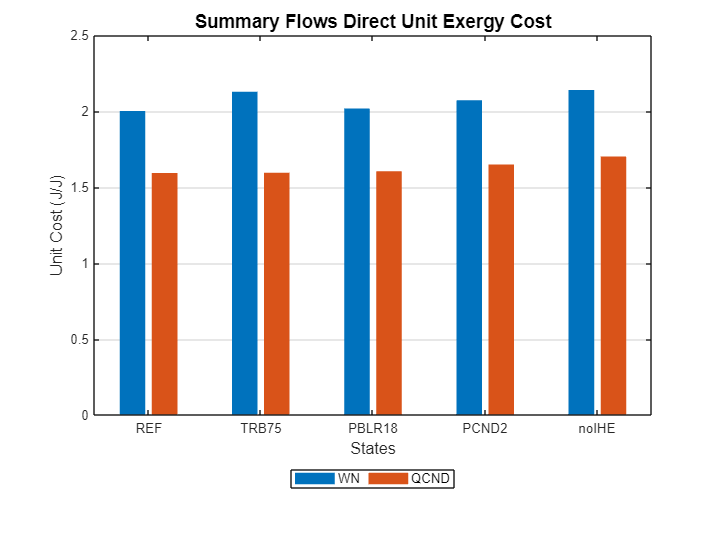

model.showGraph(cType.Tables.SUMMARY_FLOW_UNIT_COST);

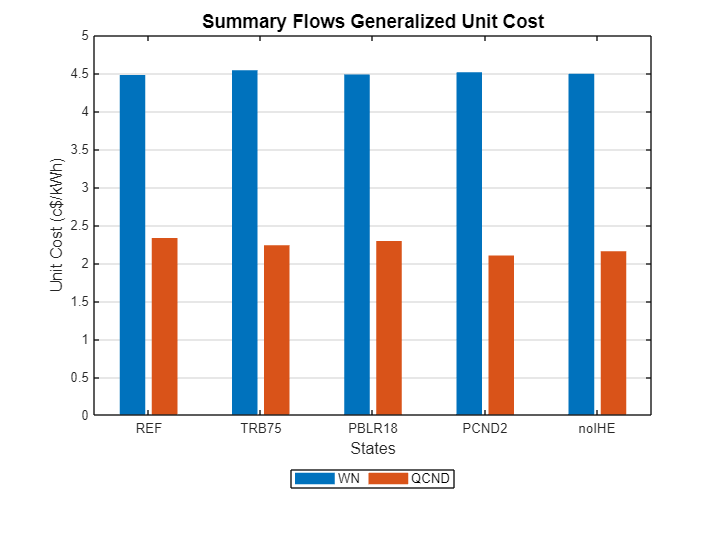

model.showGraph(cType.Tables.SUMMARY_FLOW_GENERAL_UNIT_COST);

#### (5) Diagnosis Analysis

Analyze a malfunction in the turbine (TRB75)

model.State='TRB75';
model.summaryDiagnosis;

Fuel Impact:     6.3000 (kW)
Malfunction Cost:     6.3000 (kW)


ShowResults(model,'Table',cType.Tables.DIAGNOSIS);

Diagnosis Summary

Key        MF(kW)      ΔI(kW)     ΔPt(kW)     MF*(kW)     MR*(kW)    ΔPt*(kW)
——————————————————————————————————————————————————————————————————————————————
BLR       -0.3773      1.3300      0.0000     -0.3773     -0.0742      0.0000
TRB        3.9915      4.0480      0.0000      5.6004      1.0639      0.0000
IHE        0.0239      0.1530      0.0000      0.0362      0.0243      0.0000
PMP        0.0001      0.0250      0.0000      0.0002      0.0021      0.0000
CND        0.0000      0.7440      0.0000      0.0155      0.0089      0.0000
ENV        3.6383      6.3000      0.0000      5.2750      1.0250      0.0000



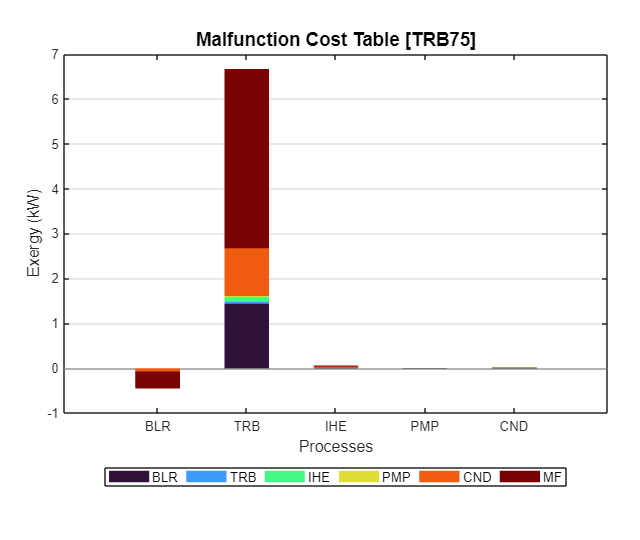

ShowGraph(model,'Graph',cType.Tables.MALFUNCTION_COST,'ShowOutput',false);

#### **(4) Recycling Analysis**

Select the model without IHE and analyse the capability of recycling

model.Recycling=true;
model.DiagnosisMethod='NONE';
model.State='noIHE';
ShowResults(model,'Table',cType.Tables.WASTE_RECYCLING_GENERAL);

Generalized Cost Recycling Analysis (c$/kWh)

 Recycle (%)            WN       QCND
——————————————————————————————————————
      0             4.4914     2.1559
     10             4.4401     2.1158
     20             4.3907     2.0772
     30             4.3431     2.0400
     40             4.2971     2.0041
     50             4.2528     1.9694
     60             4.2099     1.9360
     70             4.1685     1.9036
     80             4.1284     1.8723
     90             4.0897     1.8420
    100             4.0521     1.8127



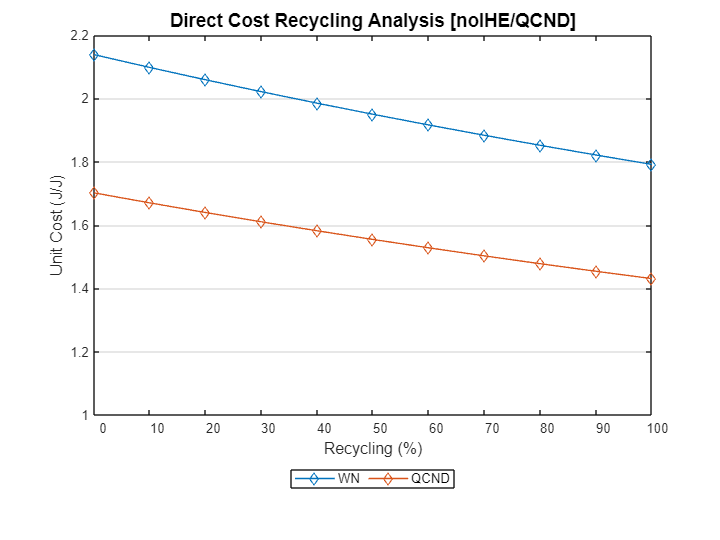

ShowGraph(model,'Graph',cType.Tables.WASTE_RECYCLING_DIRECT);

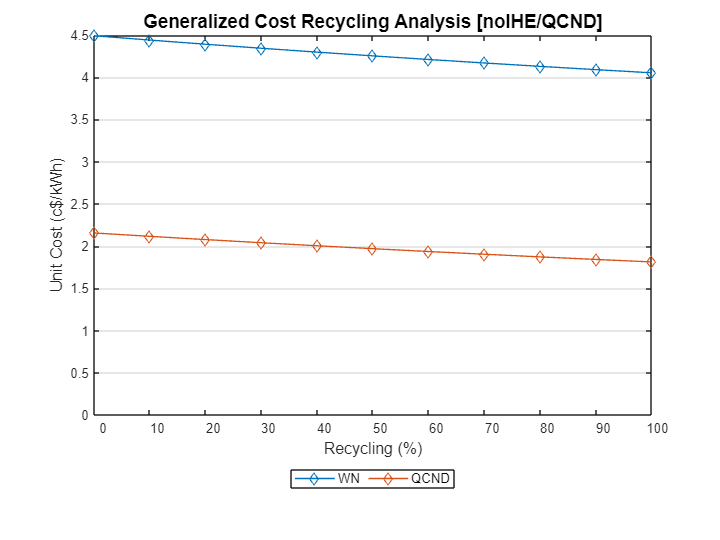

ShowGraph(model,'Graph',cType.Tables.WASTE_RECYCLING_GENERAL);